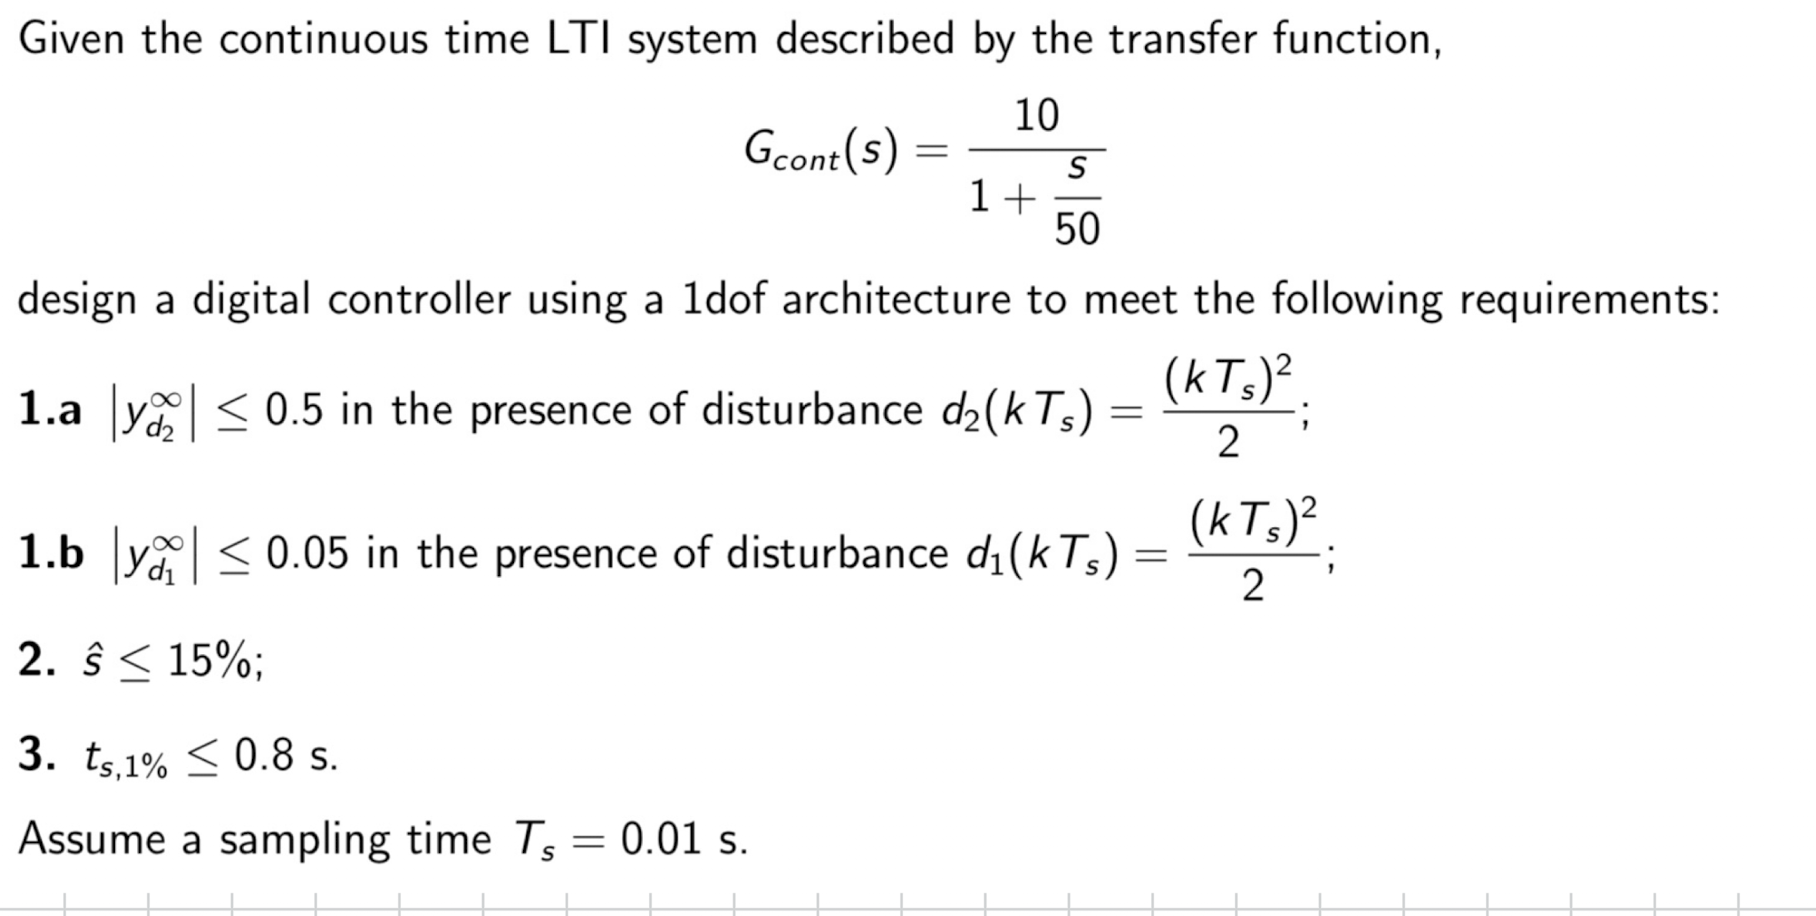

close all
clear
clc

Ts = 0.01;
s = tf('s');
z = tf('z',Ts);

Gcont = 10/(1+s/50);

G = zpk(c2d(Gcont,Ts,'zoh'))


G =
 
    3.9347
  ----------
  (z-0.6065)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.


[zG, pG, kG] = zpkdata(G,'v');

B = kG;
A = [1 -pG];

#### Steady state

l1 = 0;
l2 = 2;
l = l1 + l2;
n_add = 1;

#### Transient response

s_hat = 0.15;
ts = 0.8;

zeta = abs(log(s_hat))/(sqrt(pi^2 + log(s_hat)^2)); % formulario

wn = 4.6/(zeta*ts); % formulario

From the pzplot (not plotted) we can see that we can cancel the G pole 

A1 = A;
Aplus = A;
Aminus = 1;
Bplus = 1;
Bminus = kG;

Let's now compute degrees of R S and Am

deg_A = 1;
deg_A_minus = 0;
deg_A_plus = 1;
deg_B_plus = 0;
deg_B_minus = 0;

deg_S1 = l + deg_A_minus - 1 + n_add

deg_S1 = 2

deg_R2 = deg_A - deg_B_plus + l1 - 1 + n_add

deg_R2 = 1

deg_Am = l + deg_A + deg_A_minus + l1 - deg_B_plus - 1 + n_add

deg_Am = 3

Since deg(Am) = 3 we need 3 extra poles. We choose a pair of complex conjugate poles and a real pole

% NO NEL FORMULARIO!!!! DA SAPERE

p1c = -zeta*wn + 1j*wn*sqrt(1-zeta^2);
p1 = exp(p1c*Ts); % sampling transformation -> I get the pole value in DT
p2c = -zeta*wn - 1j*wn*sqrt(1-zeta^2);
p2 = exp(p2c*Ts); 

p3c = -5*zeta*wn; % this real pole is faster than p1 and p2
p3 = exp(p3c*Ts);
Am = poly([p1 p2 p3]);

Now we have to build extra equations

A_plus_1 = polyval(Aplus,1);
extra_eq = [-20*Ts^2*ones(1,2) +A_plus_1*ones(1,3)]

extra_eq =    -0.0020   -0.0020    0.3935    0.3935    0.3935


Let's solve dioph eq

Adioph = conv([1 -1], conv([1 -1], Aminus));
Bdioph = Bminus;

[R2, S1, Ms] = diop_solver(Adioph, Bdioph, Am, deg_R2, n_add, extra_eq)

R2 =     1.0000   -0.8541


S1 =     0.0570   -0.1034    0.0471


Ms =     1.0000         0         0         0         0
   -2.0000    1.0000    3.9347         0         0
    1.0000   -2.0000         0    3.9347         0
         0    1.0000         0         0    3.9347
   -0.0020   -0.0020    0.3935    0.3935    0.3935



% build controller
R = conv([1 -1], conv([1 -1], R2));
S = conv(Aplus, S1);

C = zpk(tf(S,R,Ts))


C =
 
  0.057007 (z-0.6065) (z^2 - 1.814z + 0.8269)
  -------------------------------------------
              (z-1)^2 (z-0.8541)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.


Now let's simulate

Let's check transient response parameters

Tend = 20;
step_value = 1;
y_delta_1 = 0;
y_delta_2 = 0;

sim = sim("simulation_lab3.slx");

y = sim.y;
r = sim.r;


figure(1)
plot(y.time, y.data, linewidth=1.5)
hold

Current plot held


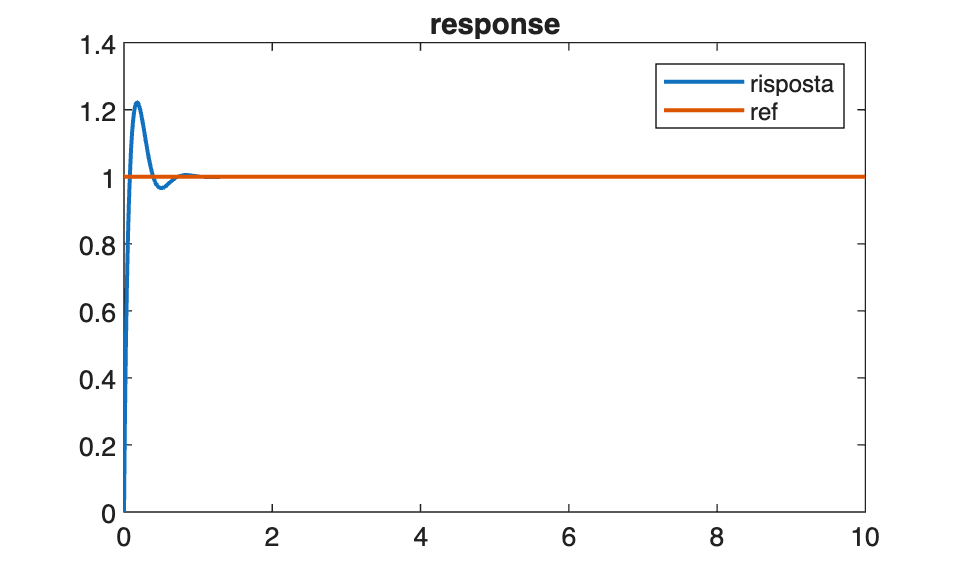

plot(r.time, r.data, linewidth=1.5)
legend("risposta","ref")
title("response")

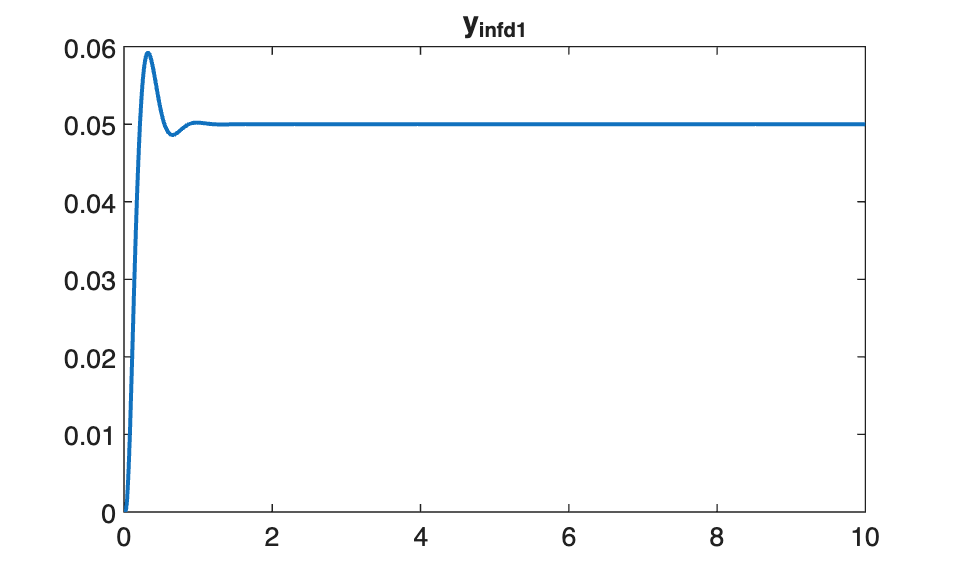


clear sim

step_value = 0;
y_delta_1 = 1;
y_delta_2 = 0;

sim = sim("simulation_lab3.slx");
y = sim.y;

figure(2)
plot(y.time, y.data, linewidth=1.5)
title("y_{inf}_{d1}")

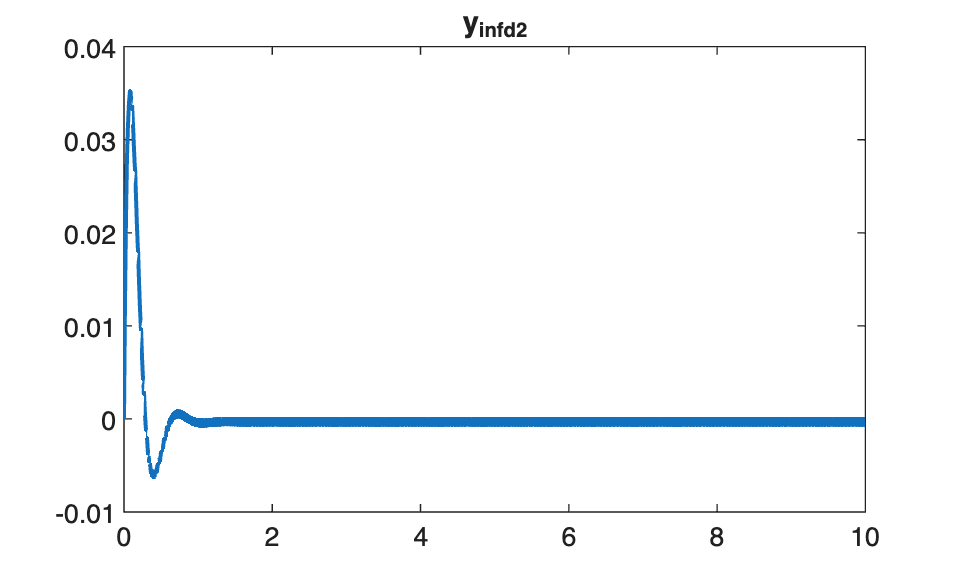

clear sim
clear y_delta_1
clear y_delta_2
step_value = 0;
y_delta_1 = 0;
y_delta_2 = 1;

sim = sim("simulation_lab3.slx");
y = sim.y;

figure(3)
plot(y.time, y.data, linewidth=1.5)
title("y_{inf}_{d2}")